# HDG scheme to poisson equation

#### Un método de Galerkin Discontinuo Hibridizable para la ecuación de Schrödinger estacionaria lineal

Resultados preliminares de *@alujan*

clear
format short
syms x y z real

% Let's add to the path the src and drivers: Original Article
addpath('/Users/chubbs/Library/CloudStorage/GoogleDrive-alujan@unal.edu.co/Shared drives/HDG - HHO -SCHRODINGER/MATLAB/949_Sayas/Matlab/Drivers/')
addpath('/Users/chubbs/Library/CloudStorage/GoogleDrive-alujan@unal.edu.co/Shared drives/HDG - HHO -SCHRODINGER/MATLAB/949_Sayas/Matlab/Src/')

% Let's add the path of the gmsh structure: Load Mesh structure
addpath('/Users/chubbs/Library/CloudStorage/GoogleDrive-alujan@unal.edu.co/Shared drives/HDG - HHO -SCHRODINGER/MATLAB/gmsh/')

% Let's add the path of the structures created: Spectral definitions
addpath('/Users/chubbs/Library/CloudStorage/GoogleDrive-alujan@unal.edu.co/Shared drives/HDG - HHO -SCHRODINGER/MATLAB/spectral')

## 0. Preliminaries

Load of structures and previous definitions.

#### Load of structures for analisys

Let's load the reference structres we're going to use to set the pilot example

% Importing of a singular structure for first case scenario: Unitary cube
T = load_mesh('cubeD2.msh')

T = struct with fields:
    coordinates: [137×3 double]
       elements: [361×4 double]
      dirichlet: [252×3 double]
        neumann: [0×3 double]
          faces: [848×4 double]
       dirfaces: [597 598 599 600 601 602 603 604 605 606 607 608 609 610 611 612 613 614 615 616 617 618 619 620 621 622 623 624 625 626 627 628 629 630 631 632 633 634 635 636 637 638 639 640 641 642 643 644 645 646 647 648 649 650 … ] (1×252 double)
       neufaces: [1×0 double]
      facebyele: [361×4 double]
    orientation: [361×4 double]
           perm: [361×4 double]
         volume: [361×1 double]
           area: [848×1 double]
        normals: [361×12 double]


% Listing of elements for growth of method testing
listT = {T};

## 1. Construction of the scheme

Definition of the equation and the main elements needed to interact and create the solutions.

#### Definitions of reference solutions

First let's define the values we're going to compare with, in this case the functions $u$ and $\mathit{\mathbf{p}}$, defined for the auxiliar equation, it's important to notice that for instance $\psi$corresponds to the wave function of the particle and $J$ to the complex conjugate of the kinetic momentum operator applied to the wave function

                                               
$$\nabla u\left(\mathit{\mathbf{r}}\right)+\mathit{\mathbf{p}}\left(\mathit{\mathbf{r}}\right)=0\;\textrm{in}\;\Omega$$


                                                    
$$-\textrm{div}\;\mathit{\mathbf{p}}\left(\mathit{\mathbf{r}}\right)=f\left(\mathit{\mathbf{r}}\right)\;\textrm{in}\;\Omega$$


                                                             
$$u\left(\mathit{\mathbf{r}}\right)=0\;\textrm{on}\;\partial \Omega$$


Take in mind this a scalar PDE, for this scenario every evaluation of the values must be in components of the vector.

% Let's define a simple value for U: harmonic vector
% - Caracteristics of the function in space
nx = 2; ny = 2; nz = 2;
U(x, y, z) = (nx^2 + ny^2 + nz^2) * pi^2 * ... 
    sin(nx * pi * x) * sin(ny * pi * y) * sin(nz * pi * z)

$$U(x, y, z) = \frac{8334140006820045\,\sin\left(2\,\pi \,x\right)\,\sin\left(2\,\pi \,y\right)\,\sin\left(2\,\pi \,z\right)}{70368744177664}$$

% Partial derivarives of the component
Ux = diff(U, x); Uxx = diff(U, x, 2);
Uy = diff(U, y); Uyy = diff(U, y, 2);
Uz = diff(U, z); Uzz = diff(U, z, 2);

Q = -[Ux; Uy; Uz]   % Gradient definition

$$Q(x, y, z) = \left(\begin{array}{c} -\frac{8334140006820045\,\pi \,\cos\left(2\,\pi \,x\right)\,\sin\left(2\,\pi \,y\right)\,\sin\left(2\,\pi \,z\right)}{35184372088832}\\ -\frac{8334140006820045\,\pi \,\cos\left(2\,\pi \,y\right)\,\sin\left(2\,\pi \,x\right)\,\sin\left(2\,\pi \,z\right)}{35184372088832}\\ -\frac{8334140006820045\,\pi \,\cos\left(2\,\pi \,z\right)\,\sin\left(2\,\pi \,x\right)\,\sin\left(2\,\pi \,y\right)}{35184372088832} \end{array}\right)$$

% Definition of potential taking action
F(x, y, z) = - (Uxx + Uyy +Uzz)

$$F(x, y, z) = \frac{25002420020460135\,\pi^{2}\,\sin\left(2\,\pi \,x\right)\,\sin\left(2\,\pi \,y\right)\,\sin\left(2\,\pi \,z\right)}{17592186044416}$$

% Processing of functions
u = matlabFunction(U, Vars={x, y, z});

qx = matlabFunction(-Ux, Vars={x, y, z});
qy = matlabFunction(-Uy, Vars={x, y, z});
qz = matlabFunction(-Uz, Vars={x, y, z});

f = matlabFunction(F, Vars={x, y, z});

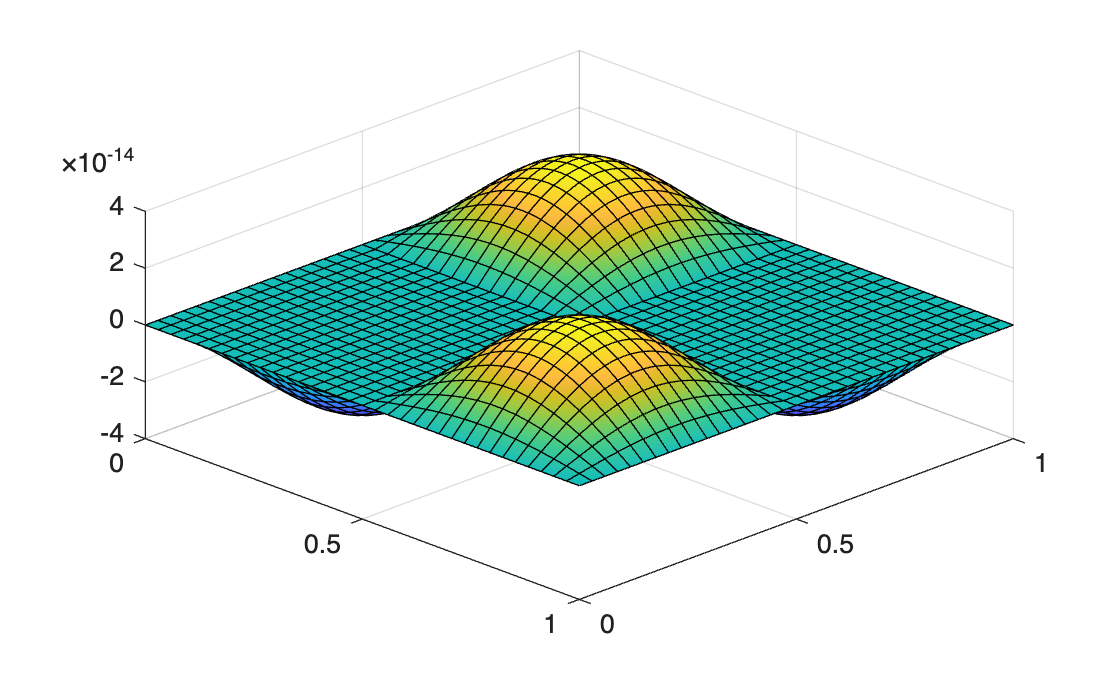

% Validation of dirichlet condition
clf('reset')

% Plot of conditions Null conditions for psi {x, y, z}
fig = figure; theme(fig,"auto");
hold on
fsurf(@(x, y) u(x, y, 0), [0 1 0 1])     % Condition for z = 0
fsurf(@(x, y) u(x, y, 1), [0 1 0 1])     % Condition for z = 1
fsurf(@(x, z) u(x, 0, z), [0 1 0 1])     % Condition for y = 0
fsurf(@(x, z) u(x, 1, z), [0 1 0 1])     % Condition for y = 1
fsurf(@(y, z) u(0, y, z), [0 1 0 1])     % Condition for x = 0
fsurf(@(y, z) u(1, y, z), [0 1 0 1])     % Condition for x = 1

hold off
grid on
view([45, 45])

#### Definition of Cuadrature and Polynomial degrees

Now for the first definitions for the method, we must import the cuadrature that's going to be used, and the polynomial degree that's going to be used for the solution

% It's possible to change the values below to alter the polynomial and
% cuadrature precision for more general viewing
TablesQuadForm3d        % Importing of cuadrature for thetrahedron
TablesQuadForm          % Importing of cuadrature for triangles

k = 3;  % Polynomial Degree

% Switch case for the selection of formulas: cuadratures
switch k
    case 0 
        formulas={tetra3,tetra1,matrix0,matrix4};
    case 1
        formulas={tetra5,tetra3,matrix4,matrix9};
    case 2
        formulas={tetra7,tetra5,matrix9,matrix11};
    case 3
        formulas={tetra9,tetra7,matrix11,matrix14};
    case 4
        formulas={tetra9,tetra9,matrix14,matrix16};
end

% Reduction of weights: Sum of weights it's defined to be equal to 2, for
% normalization it's reduced to 1.
formulas{3}(:,4)=formulas{3}(:,4)/2;
formulas{4}(:,4)=formulas{4}(:,4)/2;

#### Norm of solutions for error definitions

The `errorElem `function it's used for this task, the idea used it's comparison with the origin that leaves the norm of elements $\mathit{\mathbf{u}}$and $\mathit{\mathbf{q}}$with known solution


$$|\mathit{\mathbf{p}}-{\mathit{\mathbf{p}}}^* |_{L^2 } \;=|\mathit{\mathbf{p}}|_{L^2 } \;:{\mathit{\mathbf{p}}}^* =0$$


% Error elements definition for display handle
ErrorU=[];
ErrorQ=[];
ErrorUhat=[];

ErrorPu=[];
ErrorPuhat=[];
ErrorUstar=[];
h=[];

% Norms of unknowns for relative error
Tmax=listT{end};                    % Listing of T elements
Nelts=size(Tmax.elements,1);        % Number of elements enlisted
d3=nchoosek(k+3,3);                 % d_i definition of set (cardinality)

## 2. Scheme definition

Definition of the main iteration, mesh elements and bilinear forms

#### HDG: The main iteration

Firstly the method it's created to run in a single run *(presence of one element only)*, with this in mind, when going to expand the idea must be iterated over the different structures

% Definition of the action of tau: Identity
tau = ones(4,Nelts);

% -------------------------------- HDG 3D main function --------------------------------------- %

% Definitions asociated with the tetrahedrization
d2 = nchoosek(k+2,2);    
d3 = nchoosek(k+3,3); 

block3 = @(x) (1+(x-1)*d3):(x*d3);

Nelts  = size(T.elements,1);
Nfaces = size(T.faces,1);
Ndir   = size(T.dirichlet,1);
Nneu   = size(T.neumann,1);

% 4th intervention
% - Faces
face = T.facebyele';                  % 4 x Nelts
face = (face(:)-1)*d2;                % First degree of freedom of each face by element                                               
face = bsxfun(@plus,face,1:d2);       % 4*Nelts x d2 (d.o.f. for each face)                                              
face = reshape(face',4*d2,Nelts);     % d.o.f. for the 4 faces of each element

[J,I] = meshgrid(1:4*d2);

R_d2 = face(I(:),:); R_d2=reshape(R_d2,4*d2,4*d2,Nelts);   % Mesh grid definition inside T_i element "Row-Axis"
C_d2 = face(J(:),:); C_d2=reshape(C_d2,4*d2,4*d2,Nelts);   % Mesh grid definition inside T_i element "Column-Axis"

% - Volumes
element = (1:Nelts);                          % Nelts
element = (element(:)-1)*4*d3;                % First degree of freedom of each face by element                                               
element = bsxfun(@plus,element,1:4*d3);       % 4*Nelts x d2 (d.o.f. for each face)                                              
element = reshape(element',4*d3,Nelts);       % d.o.f. for the 4 faces of each element

[J,I] = meshgrid(1:4*d3); 

R_d3 = element(I(:),:); R_d3 = reshape(R_d3,4*d3,4*d3,Nelts);   % Mesh grid definition inside T_i element "Row-Axis"
C_d3 = element(J(:),:); C_d3 = reshape(C_d3,4*d3,4*d3,Nelts);   % Mesh grid definition inside T_i element "Column-Axis"

% R_ij^K d.o.f. for local (i,j) d.o.f. in element K ; R_ij^K=C_ji^K
RowsRHS_d2 = reshape(   face,4*d2*Nelts,1);            % Definition of solution shape   
RowsRHS_d3 = reshape(element,4*d3*Nelts,1);              % Definition of solution shape   

% 4th intervention
% Dirichlet faces: defintion
dirfaces = (T.dirfaces(:)-1)*d2;          % First degree of freedom of each face by element
dirfaces = bsxfun(@plus,dirfaces,1:d2);   % Bitwise sum of dirfaces and 1:d2 > dirfaces + 1:d2
dirfaces = reshape(dirfaces',d2*Ndir,1);  % Reshape of dirfaces

% Reduced version of free
free = (1: d2*Nfaces);

% Cleaning of dirfaces: Positions not needed
free(dirfaces) = [];      % Empty of dirfaces positions on free

% Neumann faces: defintion
neufaces = (T.neufaces(:)-1)*d2;          % First degree of freedom of each face by element
neufaces = bsxfun(@plus,neufaces,1:d2);   % Bitwise sum of neufaces and 1:d2 > neufaces + 1:d2
neufaces = reshape(neufaces',d2*Nneu,1);

% Preprocessing step: Normalization of normals:
% From the structure we define the normals as a proportion of the area,
% we're removing this definition
% normals   = reshape(T.normals', [3, 4*Nelts]);
% normals   = normals ./ vecnorm(normals);
% T.normals = reshape(normals, [3*4, Nelts])';

% ALR: Original definition of normals for the moment

% Reordering of values find indexes
indexes = arrayfun(@(i) find(T.facebyele == T.dirfaces(i)), 1:size(T.dirfaces, 2));

% - Map of values indexes
map = T.orientation(indexes) == -1; T.faces(T.dirfaces(map), [2 3]) = T.faces(T.dirfaces(map), [3 2]);

% Correction of orientation
T.orientation(indexes) = 1;

Now it's the point to use the local solvers, here are defined the change of basis and the change on the matrices for calculations needed.

% ----------------------------- Local solvers definition function ------------------------------ %

% Computation of the differentials form Matrix: Return in the already desired form
% - Computation of f test
f_test = testElem(f,T,k,formulas{1});
Af_w   = zeros(4*d3,Nelts);            % Storage reservation (4 x d3 x Nelts)

Af_w(3*d3+1:4*d3,:)=f_test;            % "Last Column" Igualation with F

% - Computation of Convection Integrals
[CMx, CMy, CMz] = ConvMatrix(T,k,formulas{1});

% - Computation of the Mass Integrals
Mass = MassMatrix(T,{@(x, y, z) 0*x.*y.*z + 1, @(x, y, z) 0*x.*y.*z}, ...
                                                            k,formulas{1});
% - ALR: Reduce this computation into one single line
Mi=Mass{1};

% - Computation of Faces Integrals
[tauPP,tauDP,nxDP,nyDP,nzDP,tauDD]=matricesFace(T,tau,k,formulas{3});

% Condensation of matrices known
nDP = [nxDP, nyDP, nzDP]; divPP = [CMx, CMy, CMz];

% - Matrices defintions: A solvers local
A1=zeros(6*d3,6*d3,Nelts);    % Solver storage reservation
A2=zeros(6*d3,4*d2,Nelts);    % Solver storage reservation
A3=zeros(6*d3,6*d3,Nelts);    % Solver storage reservation
A4=zeros(4*d2,6*d3,Nelts);    % Solver storage reservation

% Matrices related to solvers
% - Definition of the Mass matrix asociated with a_1: 6*d3 x 6*d3
O = zeros(d3,d3,Nelts);   % Big O cero matrix: Shapes juntions

% - Block definition of matrix
Mk = [Mi ,O  ,O   ; ...
      O  ,Mi ,O   ; ...
      O  ,O  ,Mi ];

A1 = [    Mk, -permute(divPP, [2 1 3]); ...
       divPP,  tauPP                 ];

% - Definition of  the Mass matrix asociated with a_2: 6*d3 x 2*(4*d2)
%   Pendiente la revisión de errores propuesta
A2 = [-permute(nDP  , [2 1 3])  ; ...
       permute(tauDP, [2 1 3]) ];

Ov = [O, O, O];                % Big O cero matrix: Shapes juntions

A4 = [Mk ,permute(Ov, [2, 1, 3]) ; ...
      Ov ,tauPP                 ];

O = zeros(d3,4*d2,Nelts);

A5 = [O; O; O; permute(tauDP, [2 1 3]) ];

% Matrices defintions: C solvers Flux
CM = zeros(4*d2,4*d2,Nelts);      % Solver storage reservation
Cf = zeros(4*d2,Nelts);           % Solver storage reservation   

CM_w = A1; Cf_w = Af_w;           % Solvers in source problem

% Parallel creation of flux operators
% Revisión del sistema final a generar
% CM(:,:,i) = -A4(:, :, i)  * (A1(:, :, i) \ (A1(:, :, i) \ A3(:, :, i) )) * A2(:, :, i);

parfor i=1:Nelts            
    CM(:,:,i) = A2(:, :, i)' * (A1(:, :, i)' \ A4(:, :, i)) * (A1(:, :, i) \ A2(:, :, i)) - ...
                A2(:, :, i)' * (A1(:, :, i)' \ A5(:, :, i)) - ...
                A5(:, :, i)' * (A1(:, :, i)  \ A2(:, :, i)) + tauDD(:, :, i);
    Cf(:, i) = A2(:, :, i)' * (A1(:, :, i)' \ Af_w(:, i));
end

% Recovery of all elements
M   = sparse(R_d2(:),C_d2(:),CM  (:)); phif   = accumarray(RowsRHS_d2,Cf  (:));
M_w = sparse(R_d3(:),C_d3(:),CM_w(:)); phif_w = accumarray(RowsRHS_d3,Cf_w(:));

% Boundary conditions evaluation
% The resulting terms are:
%  - uhartD : Reference term evaluation on the Dirichlet faces
%  - qhatN  : Reference term evaluation on the Neumann faces
[etahatD, qhatN] = BC3d(@(x, y, z) 0*x,@(x, y, z) 0*x,@(x, y, z) 0*x,@(x, y, z) 0*x,T,k,formulas{3});

% Dirichlet BC: Storage
etahatD=reshape(etahatD,d2*Ndir,1); % uhatD stored as a vector: (2*d2*Ndir) x 1 : todo > Adjust space
Etahatv=zeros(d2*Nfaces, 1);        % Storage reservation
Etahatv(dirfaces)=etahatD;          % Uhat stored as a vector: d2*Nfaces

% RHS Re-assemly
rhs=zeros(d2*Nfaces,1);                 % Storage reservation: RHS
rhs(free)=phif(free);                   % phi f from accumarray evaluation on free faces
qhatN=reshape(qhatN,d2*Nneu,1);         % qhatN stored as a vector: d2 * Nneu x 1

% Construction of RHS from the equation (5.3) : Denominator terms.
rhs(neufaces)=rhs(neufaces)+qhatN;        % Perturbation on Neumann faces from the BC3D
rhs=rhs-M(:,dirfaces)*Etahatv(dirfaces);  % Perturbation on Dirichlet faces from the BC3D

% Export of the system
system={M,phif, M_w, phif_w, free, dirfaces};
solvers={A1, A2, A4, A5};
Uh=[]; Qxh=[]; Qyh=[]; Qzh=[]; Uhat=[];

% RHS currently has the information of the frontier conditions 
% and the information of inner skeleton: solution of uhat
Etahatv(free) = M(free,free) \ rhs(free);    % Division by matrix A_1 (5.3)

Eta = reshape(Etahatv,d2,Nfaces);            % Reshape on d2 x Nfaces (Proyections)

% Recover of values per elements
faces = T.facebyele'; faces=faces(:);             % Recovery of faces information

eta_aux = reshape(Eta(:,faces),[4*d2,Nelts]);     % Reshape on the faces of Uhat

sol   = zeros(4*d3,Nelts);                        % Reservation of storage
sol_w = zeros(4*d3,Nelts);                       % Reservation of storage

% Parallel solution of sistem 
parfor K=1:Nelts
    sol(:,K)=A1(:,:,K)\A2(:,:,K)*eta_aux(:,K);

    sol_w(:, K) = A1(:,:,K)\Af_w(:,K);
end

% Reconstruction of volume solution

% Solution separation on coordinates
Qxh = sol(block3(1),:, :) + sol_w(block3(1),:, :);
Qyh = sol(block3(2),:, :) + sol_w(block3(2),:, :);
Qzh = sol(block3(3),:, :) + sol_w(block3(3),:, :);

Uh  = sol(block3(4),:, :) + sol_w(block3(4),:, :);

### Error comparison with solution

Now we can review our process checking if the error obtained for the process done. Let's check the associated errors.

% Norms definitions
normU=errorElem(Tmax,u,zeros(d3,Nelts),k,formulas{1});

normQ=errorElem(Tmax,qx,zeros(d3,Nelts),k,formulas{1})...
        +errorElem(Tmax,qy,zeros(d3,Nelts),k,formulas{1})...
        +errorElem(Tmax,qz,zeros(d3,Nelts),k,formulas{1});

normEta=errorFaces(T,u,zeros(size(Eta)),k,formulas{4});
    
% Errors with exact solution
error_eta= errorFaces(T,u,Eta,k,formulas{4});
error_q   = errorElem(T,qx,Qxh,k,formulas{1})...
           +errorElem(T,qy,Qyh,k,formulas{1})...
           +errorElem(T,qz,Qzh,k,formulas{1});
error_u   = errorElem(T,u,Uh,k,formulas{1});

ErrorQ=[ErrorQ error_q/normQ]

ErrorQ = 0.0134

ErrorU=[ErrorU error_u/normU]

ErrorU = 0.0462

ErrorUhat=[ErrorUhat error_eta/normEta]

ErrorUhat = 0.0149

% Rate of sucesion: Convergence verification
rateQ=log2(ErrorQ(1:end-1)./ErrorQ(2:end));
rateU=log2(ErrorU(1:end-1)./ErrorU(2:end));
rateEta=log2(ErrorUhat(1:end-1)./ErrorUhat(2:end));

% Display sequence of values
format bank
disp('Rate |Q-Qh|   Rate |U-Uh|     Rate |U-Uhat|_h');

Rate |Q-Qh|   Rate |U-Uh|     Rate |U-Uhat|_h


disp([rateQ' rateU' rateEta']);
format shortE
disp('Error |Q-Qh|   Error |U-Uh|     Error |U-Uhat|_h');

Error |Q-Qh|   Error |U-Uh|     Error |U-Uhat|_h


disp([ErrorQ' ErrorU' ErrorUhat']);

   1.3413e-02   4.6192e-02   1.4872e-02



### Solutions visualization

Now let's focus on visualizing our solutions and understanding how it behaves

% Selection of variables
p = @(x, y, z) u(x,y,z);
ph = Uh(:, :);
formula = matrix23;

x=T.coordinates(:,1); x=formula(:,1:4)*x(T.elements');
y=T.coordinates(:,2); y=formula(:,1:4)*y(T.elements');
z=T.coordinates(:,3); z=formula(:,1:4)*z(T.elements');

p=p(x,y,z);
xhat=formula(:,2);
yhat=formula(:,3);
zhat=formula(:,4);
B=dubiner3d(2*xhat-1,2*yhat-1,2*zhat-1,k);
ph=B*ph;
abs(p - ph)

ans =    3.6416e+00   1.4163e+01   3.5962e+01   4.9747e+00   2.0916e+01   3.6175e+00   1.2477e+01   2.3068e+01   2.6539e+01   8.5768e+00   6.9640e+00   1.2184e-01   2.4027e+01   1.4230e+01   4.1672e+00   3.0130e+01   1.8678e+00   5.4290e+00   5.6249e+00   1.7472e+01   2.3676e+01   2.1093e+01   1.1074e+01   4.4951e+00   3.7636e+00   1.0977e+01   1.3809e+01   2.8218e+01   1.8504e+01   2.7906e+01   3.5636e+01   2.7537e+01   2.4831e+00   1.0858e+01   7.9492e+00   3.8514e+00   1.8680e+01   1.5112e+01   1.5245e+01   2.4535e+01   2.5677e+01   8.9418e+00   1.8378e+00   1.2935e+01   1.5868e+01   8.9892e+00   4.2362e+00   4.1896e-01   1.4116e+01   1.5739e+00
   2.3274e-01   8.0466e-01   1.7294e+01   2.2826e+01   3.5193e+01   1.4361e+01   2.1333e+01   1.6458e-01   6.3564e+00   1.7009e+01   2.6385e+01   1.2197e+01   1.3176e+01   1.5442e+01   3.5925e+00   8.0787e+00   1.8318e+00   9.9055e+00   4.1067e+00   4.2681e+00   8.0395e+00   1.6985e+01   3.2268e+01   1.0708e+01   1.0958e+01   3.7794e+00   2.

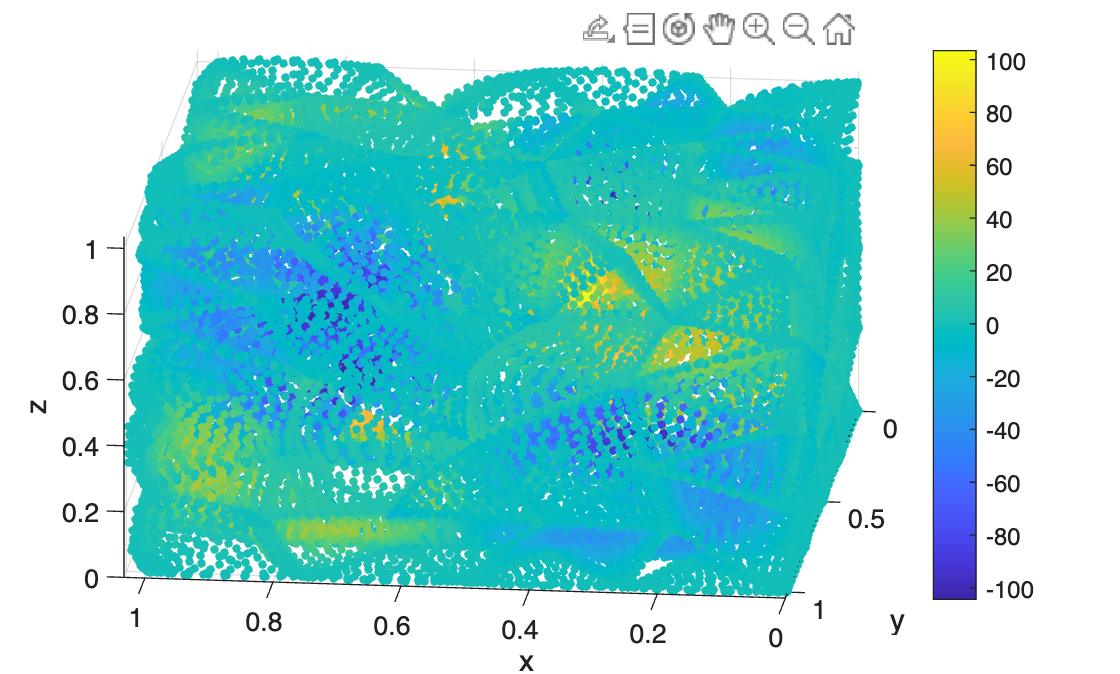

x = round(x(:), 4); y = round(y(:), 4); z = round(z(:), 4);
fig = figure; theme(fig,"auto");
scatter3(x, y, z, 10*ones(size(x(:))), ph(:), 'filled')
colorbar; clim([min(ph(:)), max(ph(:))])
xlabel('x')
ylabel('y')
zlabel('z')